% ------------------------------------------------------
A     = 1.1; % fluorescence intensity units
omega = 2.6; % rad/s
A_0   = 0.01;

u=@(t) A*sin(omega*t)+A_0;

tArray = linspace(0,1.6,200);
uArray = u(tArray); % an array of samples of u
% ------------------------------------------------------

% analytical solutions (in real life, we might not know these)
dudtExact      =  A*omega*cos(omega*tArray);
du2dt2Exact    = -A*omega^2*sin(omega*tArray);
du3dt3Exact    = -A*omega^3*cos(omega*tArray);

% Take the sample and add a bit of noise
uObserved = u(tArray) + (1e-7)*randn(size(tArray));
 
display(uObserved);

uObserved =     0.0100    0.0330    0.0560    0.0789    0.1019    0.1248    0.1476    0.1704    0.1931    0.2157    0.2383    0.2607    0.2831    0.3053    0.3274    0.3493    0.3711    0.3927    0.4142    0.4355    0.4566    0.4775    0.4982    0.5187    0.5390    0.5591    0.5789    0.5984    0.6177    0.6368    0.6555    0.6740    0.6922    0.7101    0.7276    0.7449    0.7619    0.7785    0.7948    0.8107    0.8263    0.8415    0.8564    0.8709    0.8850    0.8988    0.9121    0.9251    0.9376    0.9498


%-----------make the plot for first derivative
dt=tArray(2)-tArray(1);
dudt = diff(uObserved)./dt;
%----------make the plot for the second and third derivative
du2dt2 = diff(dudt)/dt;
du3dt3 = diff(du2dt2)/dt;

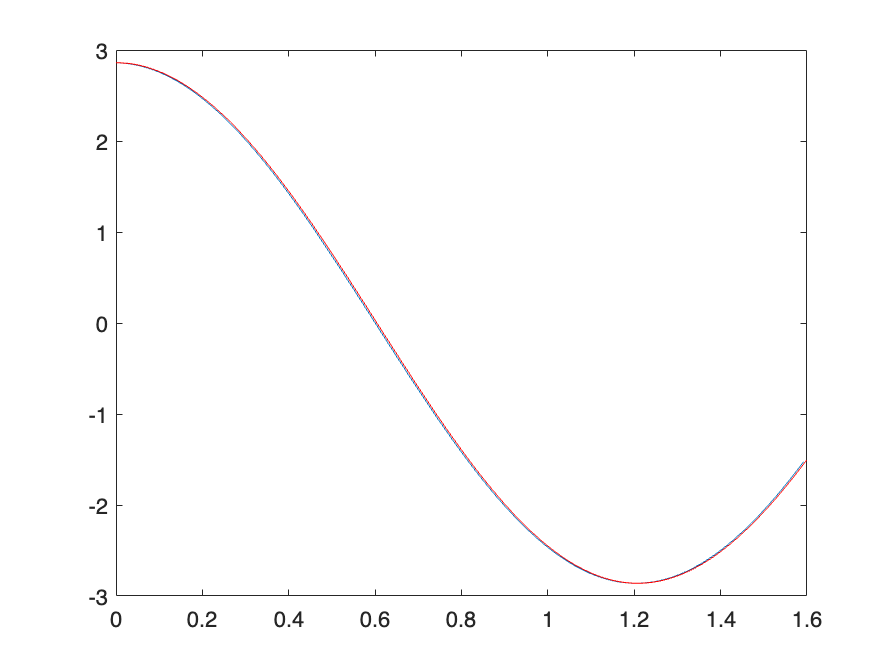

figure
plot(tArray(1:end-1), dudt); 
hold on
plot(tArray, dudtExact,"-r")

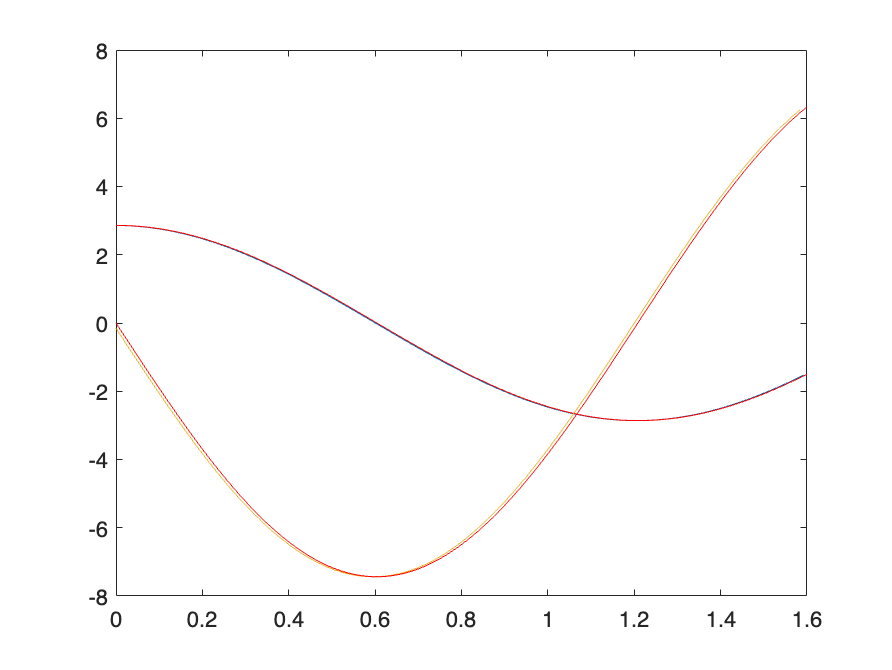

plot(tArray(1:end-2), du2dt2); 
hold on
plot(tArray, du2dt2Exact,"-r"); 

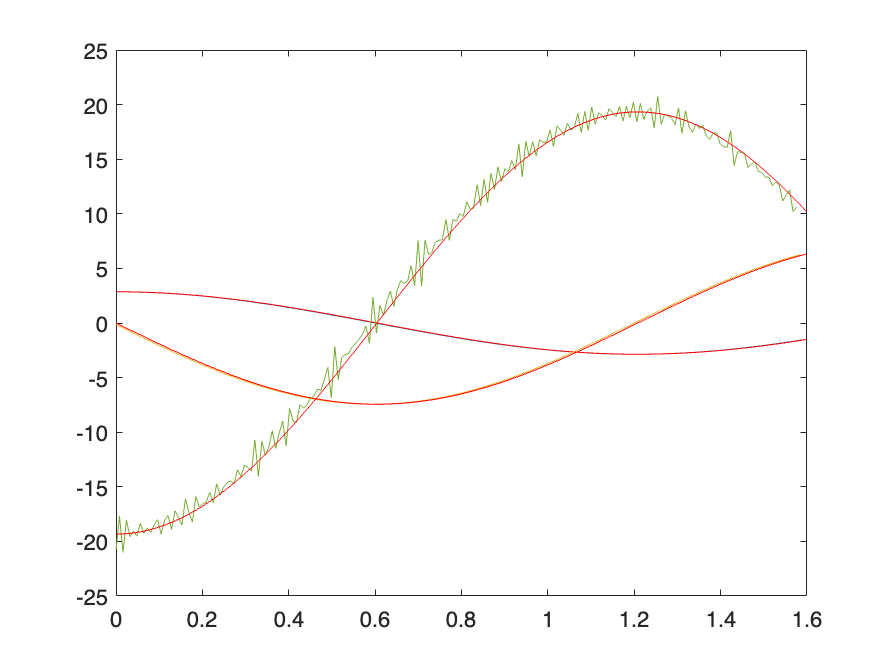

plot(tArray(1:end-3), du3dt3); 
hold on
plot(tArray, du3dt3Exact,"-r"); 

%-----3 choose noise to control absolute difference within 10%
UO =@(noise) u(tArray) + noise*randn(size(tArray));
acc = @(obs,ext) mean(abs(obs-ext));

dt=tArray(2)-tArray(1);
for n=1e-100
    dudt_uo = diff(UO(n))./dt;
    du2dt2_uo = diff(dudt_uo)/dt;
    du3dt3_uo = diff(du2dt2_uo)/dt;
    acc1=acc(dudt_uo,dudtExact(1:end-1));
    acc2=acc(du2dt2_uo,du2dt2Exact(1:end-2));
    acc3=acc(du3dt3_uo,du3dt3Exact(1:end-3));

    if (acc1<0.1 && acc2<0.1 && acc3<0.1)
    n
    end
end
